# Mohammadreza Arani

## Convex Optimization

## Project 3

## 810100511

*Electric vehicle charging. *A group of *N *electric vehicles need to charge their batteries over the next *T *time periods.  

In each time period, the total charging energy over all vehicles cannot exceed *C_*max.  [ Our Constraint] (1)

*q(t*+1*,i) *= *q(t,i) *+ *c(t,i*) [is defined]

Initial points are given for dynamic charges q1,i:

Target minimum charge level over time, given by *q(t,i) *tar ===>

*s(t,i) *= (*q(t,i) *tar *- q(t,i) )*+ ====>    charging shortfall in period*t *for vehicle *i*   [is defined]

  (*a*)+ = max*{a, *0*}*  [is defined]

#### Our ***objective*** is to minimize the mean square shortfall, given by  :

$S=\frac{1}{\left(T+1\right)*N}\Sigma {\;}_t \Sigma_i \;s_{t,i}^2$     : for t=1:T+1;

                                                   i=1:N;

[minimizing the root-mean-square (RMS) shortfall  ]

[is defiend]

#### Q1:

Explain how to solve the problem using convex optimization, and solve the following problem instance.  

We have ***N *****= 4** vehicles, ***T *****= 90** time periods, and ***C*****max = 3**. 

The **initial charges  *****q(*****1*****,i) *****are 20*****, *****0*****, *****30, and 25** , respectively.   

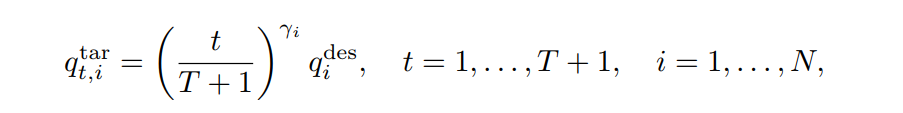

% Load data and Initialization:
clear; clc; close all;

N = 4; % Num of cars
T = 90; % Period step
C_max = 3;

q_init = [20;0;30;25];  % Initial Point --->
q = zeros(T+1,N);
q(1,:) = q_init(:);

t= [1:T+1]';
q_des = [60;100;75;125]'; % gives the fnal value of the target minimum charge level for vehicle



Lambda = [0.5, 0.3, 2.0, 0.6]; %parameter γi sets the  urgency’ of charging, with smaller values indicating more urgency

q_target = (t./(T+1)).^Lambda.*q_des; % as defined in the figure above!

The total charging period is 7*.*5 hours, and the maximum charging of 3kWh*/ *period corresponds to a real power of 36 kW. 

  Demands:

1) Give the optimal RMS shortfall  

2) Plot the target minimum charge values and optimal state of charge for each vehicle  with dashed

lines showing the target and solid lines showing the optimal charge  

3) Plot the optimal charging energies *c(t,i) *over time in a stack plot.  

                                                                            **** **Convexity of the problem** ****

In a convex problem, which can be solved using CVX package, we need to follow DCP rules and to have a feasible set not to get -inf or inf as the CVX output.

A convex problem, consists of a convex objective and  some convex/affine constraints.

here the objective as introduced is:


$$J=\frac{1}{\left(T+1\right)N}\sum_{t=1}^{T+1} \sum_{i=1}^N s_{t,i}^2$$


s is a single element which is the difference between target and current value. ==> Actually maximum (sup() ) of convex functions is convex itself!

we may show S in a quadratic form to prove its convexity!

% First, we defined the cost function to be as:
% sum_square( pos( q_hat(t,i) - ones(1,t-1)*c(1:t-1, i)  ) )
% And we faced MATLAB error!
% then we changed it with  x*max(x,0) for x = q_hat(t,i) -
% ones(1,t-1)*c(1:t-1, i) --> Again we faced MATLAB Error!
% Finally we removed pos function and got a good result but not the correct
% one!
diff = q_target - q_init';
cvx_begin


    variables c(T, N);
% q(t,i) = q(1,i) + sum( c(t',i) , t' = 1  to t-1)
    for t = 1 : T+1
        for i = 1 : N
            s_squared(t, i) =  pow_pos( diff(t,i) - ones(1,t-1)*c(1:t-1, i) , 2); % The objective!
        end
    end

    minimize( sum( sum(s_squared) )/ ((T+1)*N)    ) ; % / ((T+1)*N) ---> not effective in optimization!

    subject to

        c(:) >= 0; % Implicit COnstraint
        sum(c, 2) <= C_max; % Our Only Constraint ---sum(x,2) --> on the columns --> here is the cars
        

cvx_end

 
Calling SDPT3 4.0: 1890 variables, 810 equality constraints
------------------------------------------------------------

 num. of constraints = 810
 dim. of sdp    var  = 720,   num. of sdp  blk  = 360
 dim. of linear var  = 810
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.7e+02|8.1e+02|1.0e+07| 1.997802e+02  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.558|0.774|1.6e+02|1.8e+02|4.6e+06| 3.498047e+02 -1.430102e+04| 0:0:00| spchol  1  1 
 2|0.537|0.746|7.6e+01|4.7e+01|2.5e+06| 7.479596e+02 -2.106065e+04| 0:0:00| spchol  1  1 
 3|0.588|0.735|3.1e+01|1.2e+01|1.3e+06| 1.733105e+03 -2.534799e+04| 0:0:00| spchol  1  

for idx = 1 : T 
    q(idx+1, :) = q(idx, :) + c(idx, :); % Charging Dynamics!
end

disp("CVX_Optval : "+cvx_optval);

CVX_Optval : 78.503


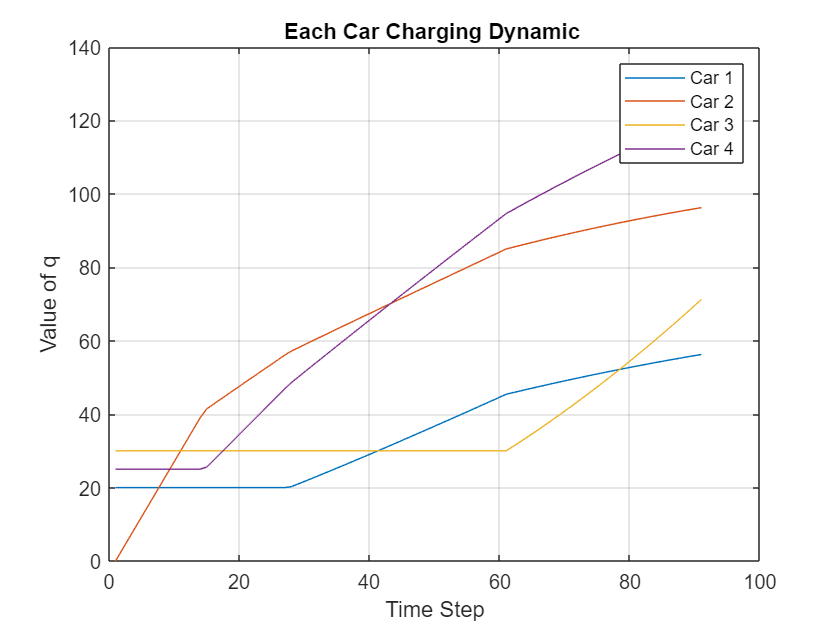


figure()
Txt = cell(N,1);
for i = 1 : N
    plot(q(:, i))
    hold on
    Txt{i} = "Car "+i;
end
xlabel('Time Step')
ylabel('Value of q')
legend(Txt)
grid on
title('Each Car Charging Dynamic ')

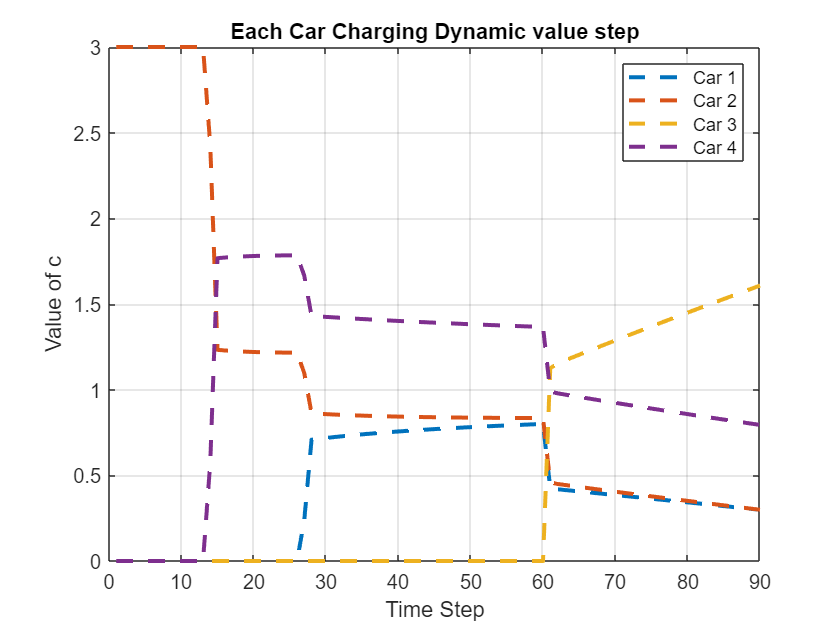


figure()
Txt = cell(N,1);
for i = 1 : N
    plot(c(:, i),'--','LineWidth', 2)
    hold on
    Txt{i} = "Car "+i;
end
xlabel('Time Step')
ylabel('Value of c')
legend(Txt)
grid on
title('Each Car Charging Dynamic value step')

% By using power of 1 we may get:
clear;

N = 4; % Num of cars
T = 90; % Period step
C_max = 3;

q_init = [20;0;30;25];  % Initial Point --->
q = zeros(T+1,N);
q(1,:) = q_init(:);

t= [1:T+1]';
q_des = [60;100;75;125]'; % gives the fnal value of the target minimum charge level for vehicle

Lambda = [0.5, 0.3, 2.0, 0.6]; %parameter γi sets the  urgency’ of charging, with smaller values indicating more urgency

q_target = (t./(T+1)).^Lambda.*q_des; % as defined in the figure above!

q2 = zeros(T+1,N);
q2(1,:) = q_init(:);

diff = q_target - q_init';
cvx_begin


    variables c2(T, N);

    for t = 1 : T+1
        for i = 1 : N
            s_2(t, i) =  ( diff(t,i) - ones(1,t-1)*c2(1:t-1, i) ).^2; % The objective! --> with power 1
        end
    end

    minimize( sum( sum(s_2) )/ ((T+1)*N)    ) ; % / ((T+1)*N) ---> not effective in optimization!

    subject to

        c2(:) >= 0; % Implicit COnstraint
        sum(c2, 2) <= C_max; % Our Only Constraint ---sum(x,2) --> on the columns --> here is the cars
        
cvx_end

 
Calling SDPT3 4.0: 1530 variables, 720 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 720
 dim. of sdp    var  = 720,   num. of sdp  blk  = 360
 dim. of linear var  = 450
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+02|2.0e+00|9.6e+05| 9.343300e+03  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.719|0.718|5.1e+01|5.5e-01|3.1e+05| 9.549513e+03 -5.116452e+01| 0:0:00| spchol  1  1 
 2|0.405|0.424|3.0e+01|3.2e-01|2.4e+05| 1.186148e+04 -9.001366e+01| 0:0:00| spchol  1  1 
 3|0.093|0.261|2.7e+01|2


for idx = 1 : T 
    q2(idx+1, :) = q2(idx, :) + c2(idx, :); % Charging Dynamics!
end

disp("CVX_Optval : "+cvx_optval);

CVX_Optval : 156.1154


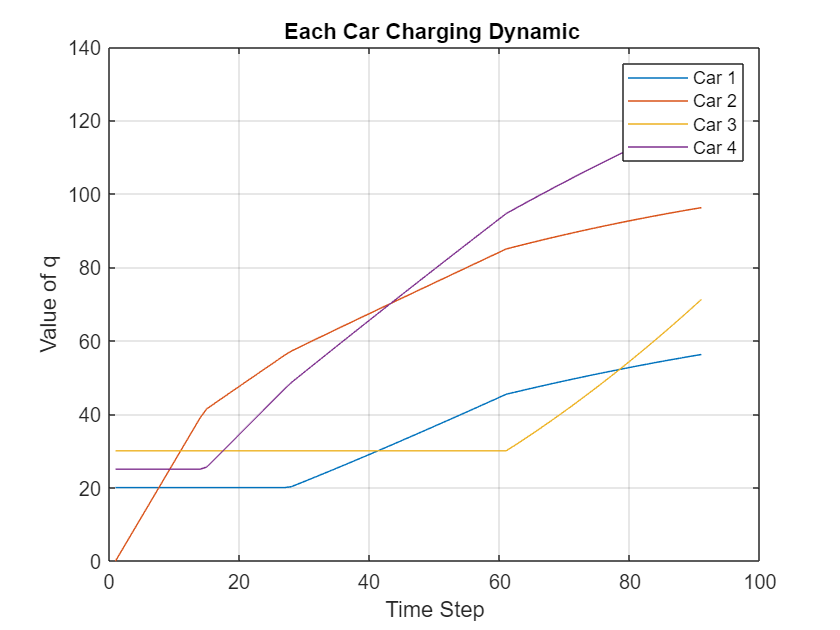

figure()
Txt = cell(N,1);
for i = 1 : N
    plot(q2(:, i))
    hold on
    Txt{i} = "Car "+i;
end
xlabel('Time Step')
ylabel('Value of q')
legend(Txt)
grid on
title('Each Car Charging Dynamic ')

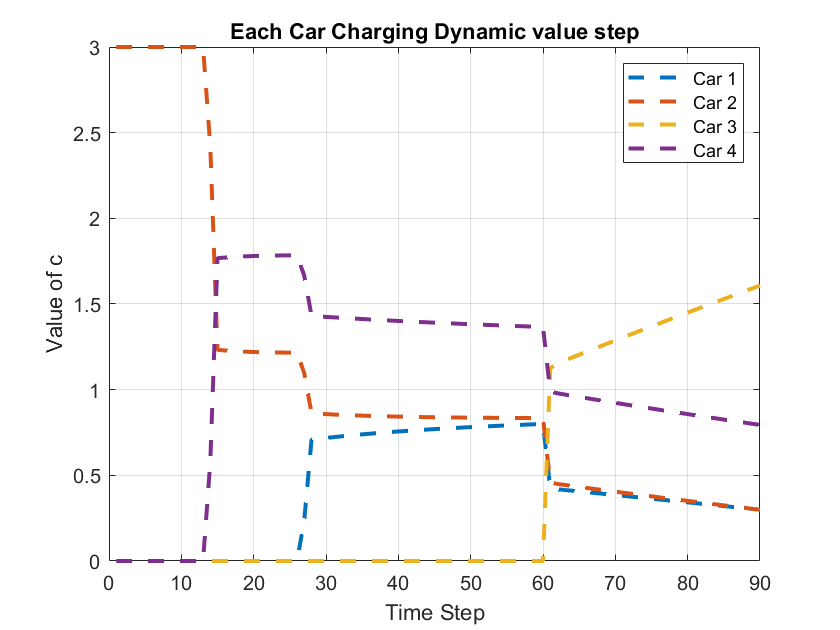

figure()
Txt = cell(N,1);
for i = 1 : N
    plot(c2(:, i),'--','LineWidth', 2)
    hold on
    Txt{i} = "Car "+i;
end
xlabel('Time Step')
ylabel('Value of c')
legend(Txt)
grid on
title('Each Car Charging Dynamic value step')

- *To compare both results, we can see that the objective value differs but we get the same output patter!*

### *Now the constant problem:*

Theta  =    (q_des - q_init) /   sum(q_des - q_init)  ; % Dividing the gap between destination and initial point to num of difference
% Gives the linear step to reach from init to destination!

C_const = Theta * C_max; 

% C_const = repmat(C_const, T, 1);  % Having C for period T!
% q(t,i) = q(1,i) + sum( c(t',i) , t' = 1  to t-1)

for t = 1 : T+1
    for i = 1 : N
        S_cons(t, i) = pow_pos( diff(t,i) - C_const(i), 2); % --> equals to  sum_square( pos(x) )
    end
end

q_cons = zeros(T+1,N);
q_cons(1,:) = q_init(:);


for idx = 1:T+10
    q_cons(idx+1 , :) =   q_cons(idx , :)  +  C_const'; % Charging Dynamics with constant C !
end


disp("Even after 10 steps more than T steps the difference remains: ")

Even after 10 steps more than T steps the difference remains: 


disp(q_cons(end,:)-q_target(end,:)) % some goes higher and some are still left behind!

   33.8259   -7.3881   19.4328  -30.8706



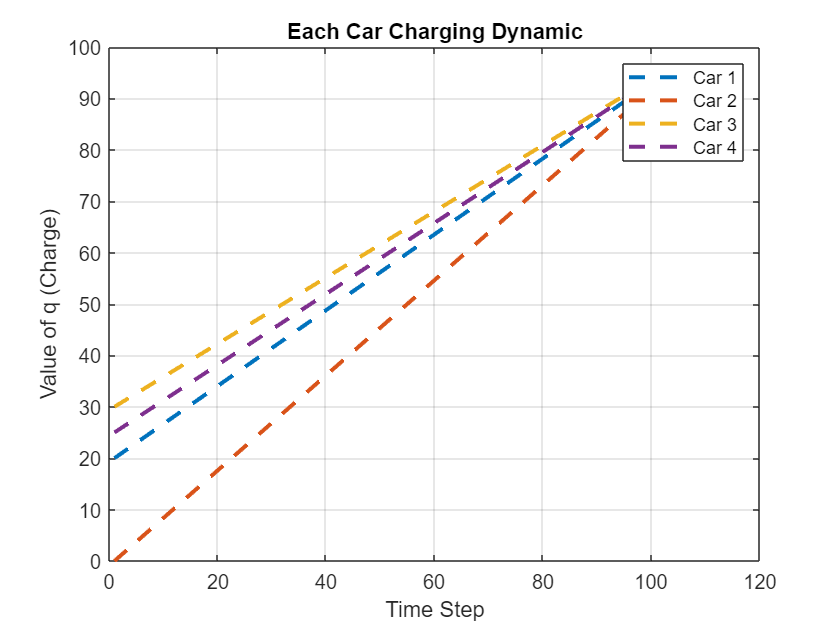

figure()
Txt = cell(N,1);
for i = 1 : N
    plot(q_cons(:, i),'--','LineWidth', 2)
    hold on
    Txt{i} = "Car "+i;
end
xlabel('Time Step')
ylabel('Value of q (Charge)')
legend(Txt)
grid on
title('Each Car Charging Dynamic')

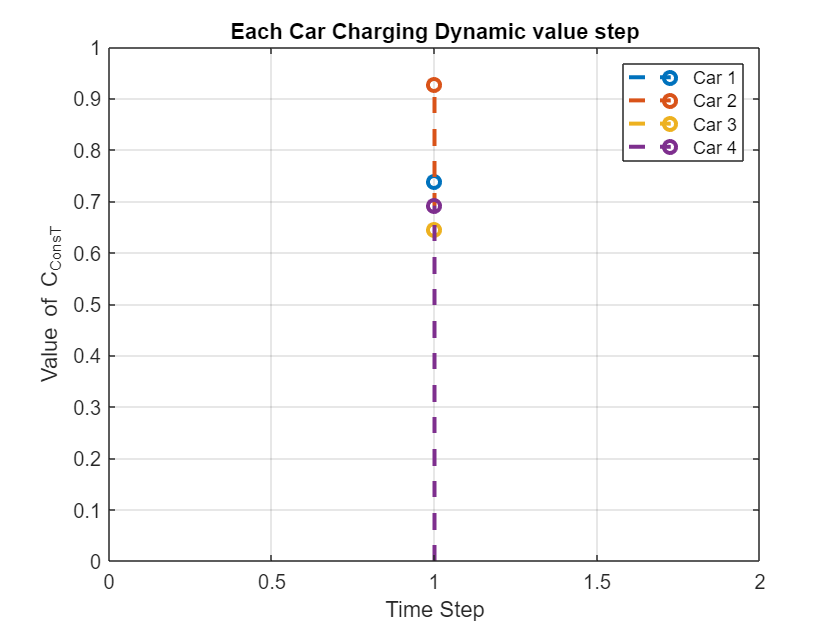


figure()
Txt = cell(N,1);
for i = 1 : N
    stem(C_const(i),'--','LineWidth', 2)
    hold on
    Txt{i} = "Car "+i;
end
xlabel('Time Step')
ylabel('Value of C_{ConsT}')
legend(Txt)
grid on
title('Each Car Charging Dynamic value step')

disp("CVX_opt_Val for the objective will be : ")

CVX_opt_Val for the objective will be : 


disp(sum(sum(S_cons))/((T+1)*N))

   2.6869e+03

